clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG

We will try to find a reference tracking controller. PC/(1+PC)

% P = 10;
% I = 0;
% D = 0;
% N = 1;
% Cs = pidGen(P,I,D,N,1);
% bodeCompare(Ps,Cs);

We see with a P controller that we will add gain, which makes it so that for low frequencies we have a positive gain. This is a good sign, but the phase of the system for low frequencies will not allow stability.

We will try to reduce the phase drop by placing the, have a better phase at low frequencies and add enough gain there. As we increase the bandwidth we reduce the amount of gain added to the system. This makes sense, because the denominator term in the controller grows. However, it is important for placing the added phase curve.

Hence it is important to find the bandwidth first, such that we have a desirable phase portrait of the controlled system, and then find the D term that matches the required gain addition.

With a N term of 1000 we have added enough bandwidth to place the phase curve over the plant in such a way that the phase crossover is around 10^3rads/s. As a criterium for stability we must have the gain crossover frequency to be lower than the phase crossover. Thus we are now limited in the amount of D gain we can add.

% P = 0;
% I = 0;
% D = 1;
% N = 1000;
% Cs = pidGen(P,I,D,N,1);
% bodeCompare(Ps,Cs);
% stepinfo(step(Ps*Cs/(1+Ps*Cs)))

We see a lot of oscilation in the step response. This is likely caused by the non-dominant pair becoming too dominant and placed poorly. This is undesirable. 

% P = 0;
% I = 0;
% D = 10;
% N = 1000;
% Cs = pidGen(P,I,D,N,1);
% bodeCompare(Ps,Cs);
% stepinfo(step(Ps*Cs/(1+Ps*Cs)))

In order to deal with this we will reduce the D gain and add gain through the P term, such that both pole pairs are effected equally. But even with a D term of one and P term to play with the system becomes too slow, of starts to show behavioural artefacts. We will therefore reduce the bandwidth and try to get a better response with more gain and less N.

Looking at the phase plot with the reduced bandwidth we see that the phase crossover frequency is only reduced slightly, while there is now more room for gain to be added before the system becomes unstable.

This give the libery to add a D and P term. First, the D term was determined to be optimal for D=40. This adds enough gain to the lower frequency register to have a quick response, while not having a large overshoot. The benefit of not having a large overshoot is that, if the overshoot does not leave the settling range, the response already settles in the rising of the transient part.

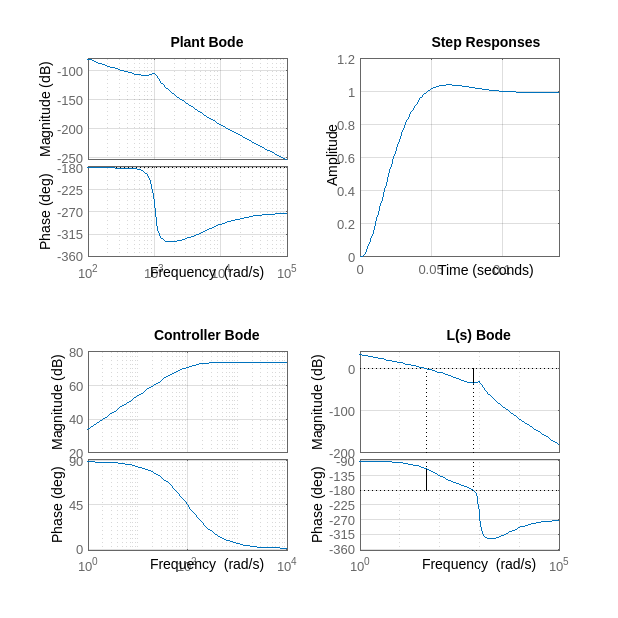

P = 0;
I = 0;
D = 50;
N = 100;
Cs = pidGen(P,I,D,N,1);
bodeCompare(Ps,Cs);

stepinfo(Ps*Cs/(1+Ps*Cs))

ans = struct with fields:
         RiseTime: 0.030294
    TransientTime: 0.084023
     SettlingTime: 0.084023
      SettlingMin: 0.90196
      SettlingMax: 1.0427
        Overshoot: 4.2738
       Undershoot: 0
             Peak: 1.0427
         PeakTime: 0.062314


We can then add a P term to add a little speed to the whole system. The drwaback of this is that the Overshoot will grow, but this might still cause the system to be faster. 

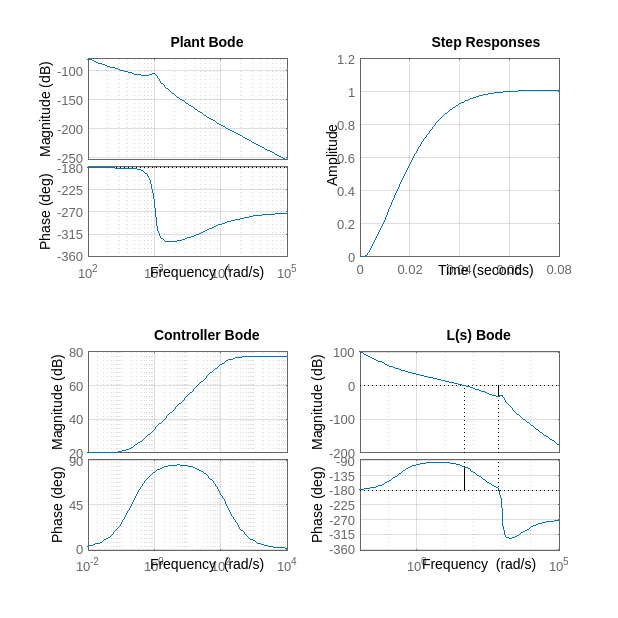

P = 10;
I = 0;
D = 50;
N = 150;
Cs = pidGen(P,I,D,N,1);
bodeCompare(Ps,Cs);

% stepinfo((Ps*Cs/(1+Ps*Cs)))

function [] = bodeCompare(Tf1,Tf2)
    fig = figure('Position',[0 0 1000 1000]);clf; hold on;  
        subplot(2,2,1)
            margin(Tf1);grid on;
            title('Plant Bode')
        subplot(2,2,2)
            % step(Tf1/(1+Tf1)); hold on;
           step(Tf1*Tf2/(1+Tf1*Tf2));grid on;
           title('Step Responses')
           % axis([0 25 -1 9])
        subplot(2,2,3)
            margin(Tf2);grid on;
            title('Controller Bode')
        subplot(2,2,4)
            margin(Tf1*Tf2); grid on;
            title('L(s) Bode')
end